# Kapittel 10.1

## E1 

### 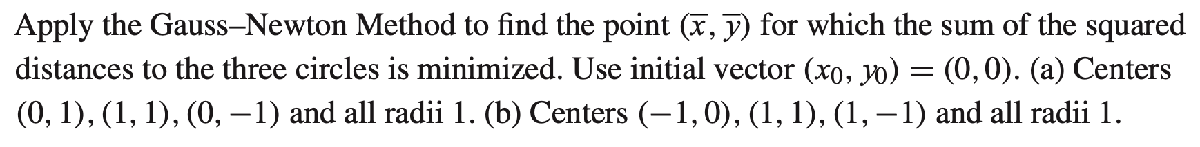

### a)

vi skal finne DFT av følgende vektor: $x=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & -1
\end{array}\right\rbrack$

vi har at:


$$\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
a_0 +{\textrm{ib}}_0 \\
a_1 +{\textrm{ib}}_1 \\
a_1 +{\textrm{ib}}_1 \\
a_1 +{\textrm{ib}}_1 
\end{array}\right\rbrack =\frac{1}{\sqrt{n}}\left\lbrack \begin{array}{cccc}
\omega^0  & \omega^0  & \omega^0  & \omega^0 \\
\omega^0  & \omega^1  & \omega^2  & \omega^3 \\
\omega^0  & \omega^2  & \omega^4  & \omega^6 \\
\omega^0  & \omega^3  & \omega^6  & \omega^9 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_0 \\
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$


som gir:


$$\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =\frac{1}{2}\left\lbrack \begin{array}{cccc}
\omega^0  & \omega^0  & \omega^0  & \omega^0 \\
\omega^0  & \omega^1  & \omega^2  & \omega^3 \\
\omega^0  & \omega^2  & \omega^4  & \omega^6 \\
\omega^0  & \omega^3  & \omega^6  & \omega^9 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1\\
0\\
-1
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =\frac{1}{2}\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & -i & -1 & i\\
1 & -1 & 1 & -1\\
1 & i & -1 & -i
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1\\
0\\
-1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
-i\\
0\\
i
\end{array}\right\rbrack$$


## E3 

## 

### c)

invers DFT av $y=\left\lbrack \begin{array}{cccc}
1 & -i & 1 & i
\end{array}\right\rbrack$ gir:


$$\left\lbrack \begin{array}{c}
x_0 \\
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =$$

$$\frac{1}{2}\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & i & -1 & -i\\
1 & -1 & 1 & -1\\
1 & -i & -1 & i
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
-i\\
1\\
i
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
1\\
1\\
-1
\end{array}\right\rbrack$$


# Kapittel 10.2

## E1 

## 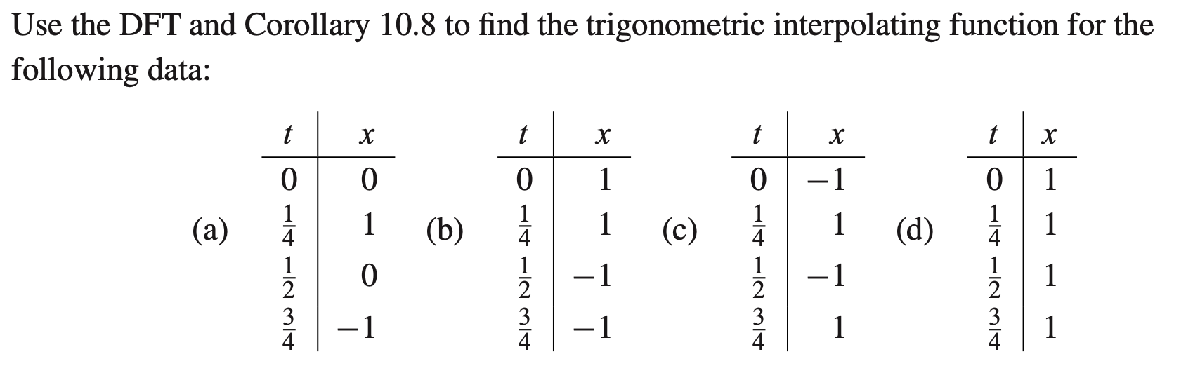

### a)

DFT av $\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & -1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & -i & 0 & i
\end{array}\right\rbrack$ (fra 10.1.a)

da får vi at: 


$$a_0 =b_0 =a_1 =b_2 =0$$
 

og at:


$$b_1 =-1\;\;,\;\;\;c=0\;\;\;\;,\;\;\;\;\;d=1$$


Da får vi ut fra korrolaret at:


$$P_2 \left(t\right)=\frac{2}{\sqrt{4}}\sin \left(\frac{2\pi t}{1}\right)=1*\sin \left(2\pi t\right)=\sin \left(2\pi t\right)$$


altså får vi interpolasjonen som ser slik ut:

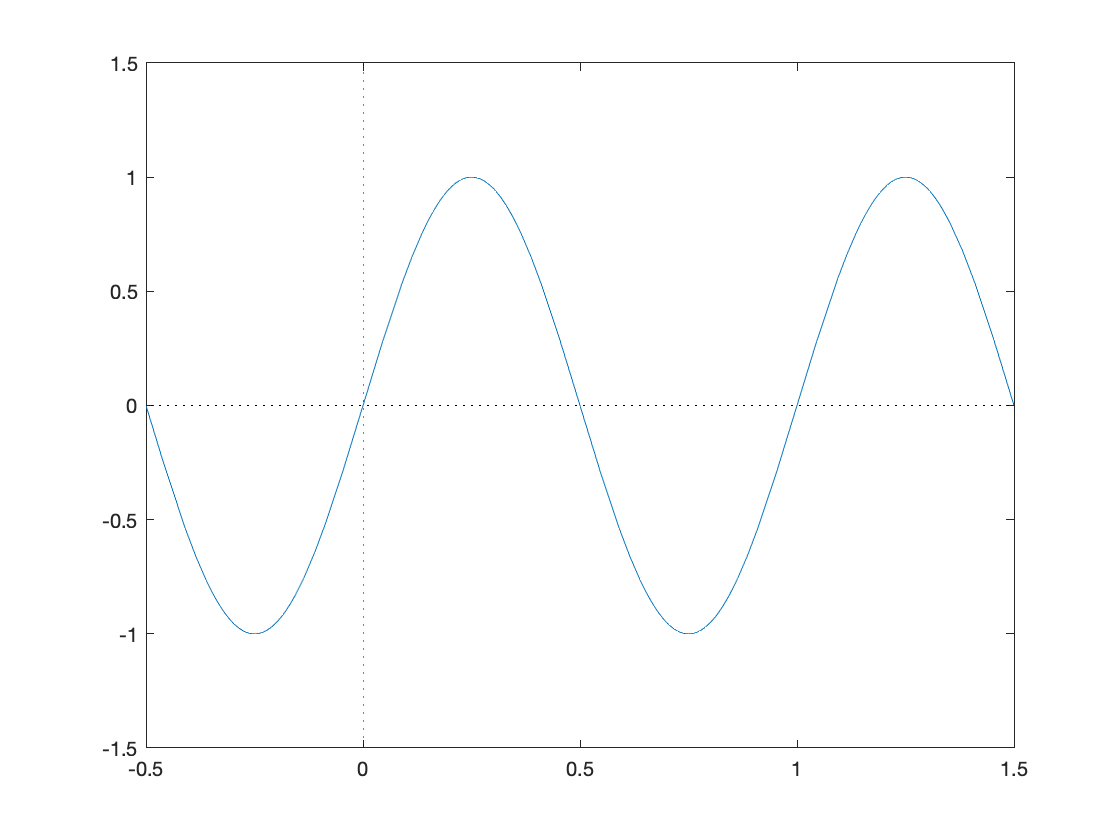

figure(1);
P2 = @(t)sin(2*pi*t);
fplot(P2,[-1 2]);
axis([-0.5 1.5 -1.5 1.5]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', ':');
line([0 0],ylim,  'Color', 'k', 'LineStyle', ':');

## CP3

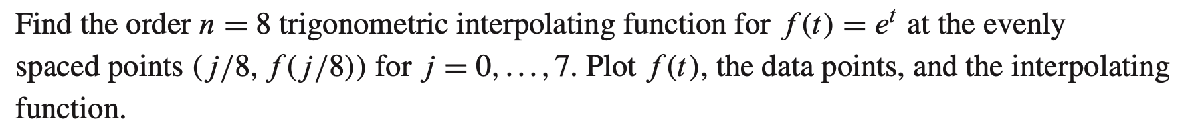


$$f\left(t\right)=e^t$$



$$\begin{array}{l}
t=\left\lbrack \begin{array}{cccccccc}
\frac{0}{8} & \frac{1}{8} & \frac{2}{8} & \frac{3}{8} & \frac{4}{8} & \frac{5}{8} & \frac{6}{8} & \frac{7}{8}
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
t\\
f\left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1/8 & \ldotp \ldotp \ldotp \\
1 & e^{1/8}  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
n=8\\
c=0\\
d=7/8
\end{array}$$


DFT = (1/sqrt(8)) * fft([exp(0) exp(1/8) exp(2/8) exp(3/8) exp(4/8) exp(5/8) exp(6/8) exp(7/8)]')

DFT =   4.562609271484386 + 0.000000000000000i
 -0.177161011060132 + 0.714246340010109i
 -0.265979687444765 + 0.301394471375234i
 -0.281554198551882 + 0.125244351847037i
 -0.284792352624637 + 0.000000000000000i
 -0.281554198551882 - 0.125244351847037i
 -0.265979687444765 - 0.301394471375234i
 -0.177161011060132 - 0.714246340010109i



$$P\left(t\right)=P_n \left(t\right)=\frac{1}{\sqrt{n}}\sum_{k=0}^{n-1} \left(a_k \mathrm{cos}\left(\frac{2\pi k\left(t-c\right)}{d-c}\right)-b_k \mathrm{sin}\left(\frac{2\pi k\left(t-c\right)}{d-c}\right)\right)$$



$$\begin{array}{l}
P_8 \left(t\right)=\frac{1}{\sqrt{8}}\sum_{k=0}^7 \left(a_k \mathrm{cos}\left(\frac{2\pi \mathrm{kt}}{7/8}\right)-b_k \mathrm{sin}\left(\frac{2\pi \mathrm{kt}}{7/8}\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;=\frac{1}{\sqrt{8}}*\\
\;\;\;\;\;\;\;\;\;\;\;\;a_0 \mathrm{cos}\left(0\right)-b_0 \mathrm{sin}\left(0\right)\\
\;\;\;\;\;\;+a_1 \mathrm{cos}\left(\frac{2\pi t}{7/8}\right)-b_k \mathrm{sin}\left(\frac{2\pi t}{7/8}\right)
\end{array}$$


figure(2);
tdata =(0:7)'/8;
xdata=exp(tdata);


$$y=\frac{1}{\sqrt{8}}*\mathrm{fft}\left(x\right)$$


y=(1/sqrt(8))*fft(xdata);
a=real(y(1:5));
b=imag(y(1:4));

P8 = @(t) a(1)/sqrt(8) ...
+(2/sqrt(8))*a(2)*cos(2*pi*t) -(2/sqrt(8))*b(2)*sin(2*pi*t)...
+(2/sqrt(8))*a(3)*cos(4*pi*t) -(2/sqrt(8))*b(3)*sin(4*pi*t) ...  
+(2/sqrt(8))*a(4)*cos(6*pi*t) -(2/sqrt(8))*b(4)*sin(6*pi*t) ...
+(1/sqrt(8))*a(5)*cos(8*pi*t);
t=(-3:131)/128;
text =( -63:171) /128; 

Plotter resultatene:

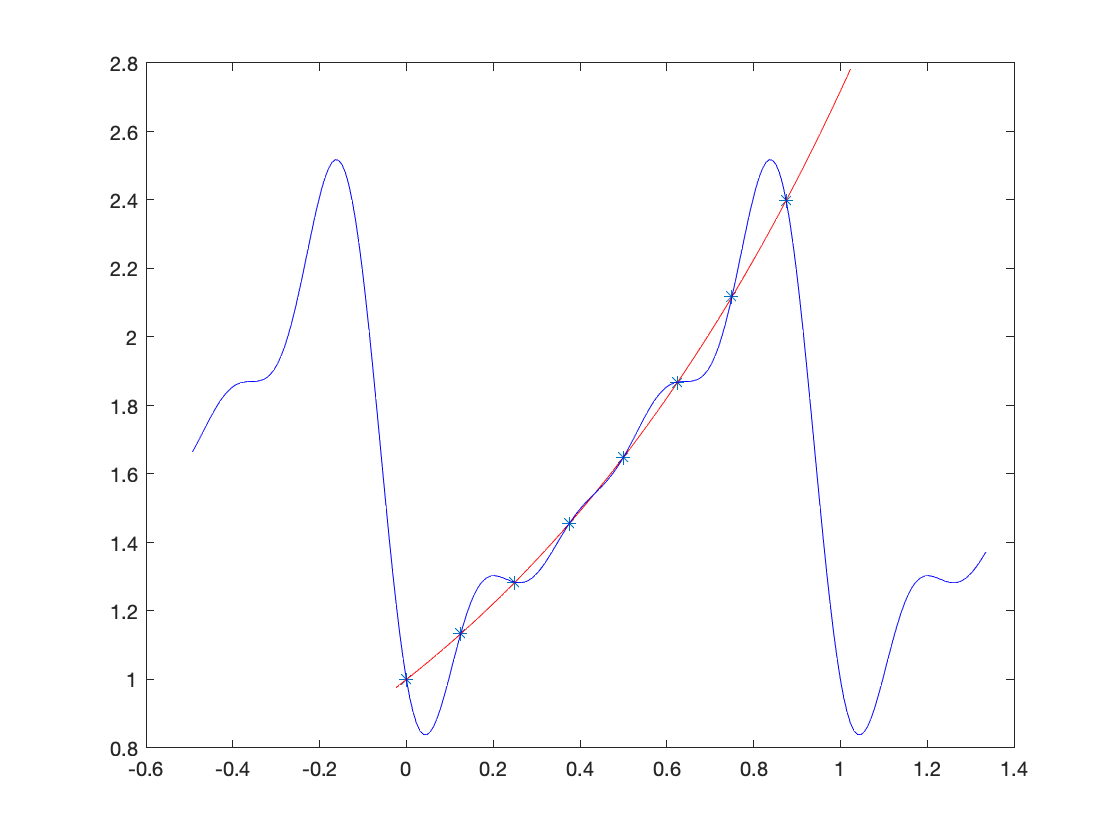

plot(tdata,xdata,'*',t,exp(t),'r',text,P8(text),'b');

# Kapittel 10.3

## E1 

### 

### a)

fra oppgave 10.2.1 a) har vi at $P_2 \left(t\right)=\sin \left(2\cdot \;\pi \cdot \;t\right)$

med basisfunksjonene 1 og $\cos \left(2\cdot \;\pi \cdot \;t\right)$får vi:


$$f\left(t\right)=0$$


# Kapittel 12.1

## E5 

## 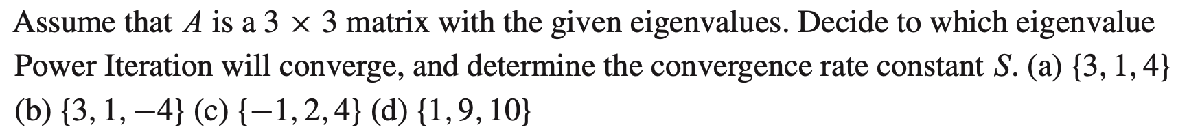

### a)

For en 3x3 matrise med egenverdiene: $\left\lbrack \begin{array}{ccc}
3 & 1 & 4
\end{array}\right\rbrack$ vil iterasjonsmetoden konvergere mot egenverdien 4

Da har vi konvergensratekonstanten: $S=\left|\frac{n}{\lambda }\right|=\left|\frac{3}{4}\right|=0\ldotp 75$

## E7 

## 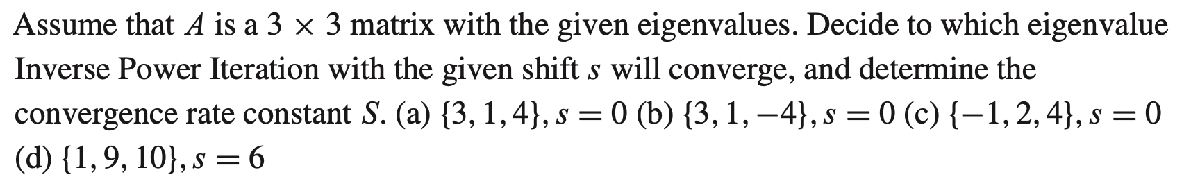

### a)				

For en 3 × 3 matrise A med egenverdier {3, 1, 4} vil invers potens iterasjonsmetoden med skift S = 0 konvergere 

mot egenverdien nærmest 0. I dette tilfellet er det λ = 1. Matrisen (A − 0I)−1 har egenverdier {1/3, 1, 1/4}. 

Konvergensratekonstanten er S = |(1/3)/1| = 1/3. 

## E8 

## 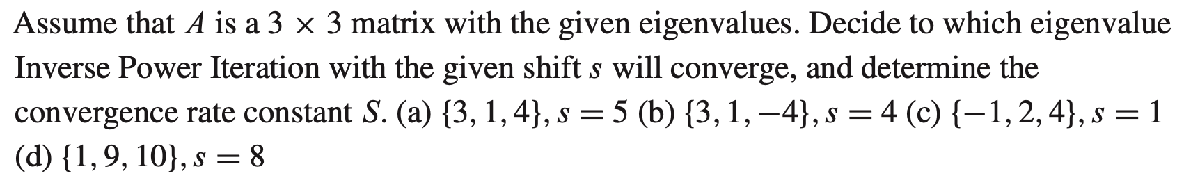

### a)

For en 3 × 3 matrise A med egenverdier {3, 1, 4} vil invers potens iterasjonsmetoden med skift S = 5 konvergere 

mot egenverdien nærmest 5. I dette tilfellet er det λ = 4. Matrisen (A − 5I)−1 har egenverdier {−1/2, −1/4, −1}. 

Konvergensratekonstanten er S = |(−1/2)/(−1)| = 1/2.  

## E9

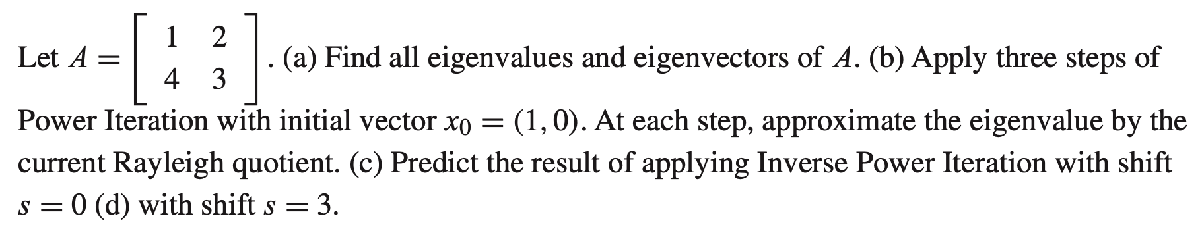

### a) 

Egenverdiene til matrisen $\left\lbrack \begin{array}{cc}
1 & 2\\
4 & 3
\end{array}\right\rbrack$ er:


$$p\left(\lambda \right)=\left\lbrack \begin{array}{cc}
1-\lambda  & 2\\
4 & 3-\lambda 
\end{array}\right\rbrack =\lambda^2 -4\lambda -5=0$$


dette gir: 

egenverdier = roots([1 -4 -5]);
fprintf('vi får egenverdiene %d og %d', egenverdier(1), egenverdier(2));

vi får egenverdiene 5 og -1

### b)

har start vektoren  $x_0 =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$

- $u_0 =x_0 /\left|\right|x_0 \left|{\left|\right.}_2 =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_1 ={\textrm{Au}}_o =\left\lbrack \begin{array}{c}
1\\
4
\end{array}\right\rbrack \right.$         rayleight kovitienten blir da: $u_0^T *x_1 =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
1\\
4
\end{array}\right\rbrack =1$

- $u_1 =x_1 /\left|\right|x_1 \left|{\left|\right.}_2 =\left\lbrack \begin{array}{c}
0\ldotp 243\\
0\ldotp 970
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;x_2 ={\textrm{Au}}_1 =\left\lbrack \begin{array}{c}
2\ldotp 183\\
3\ldotp 881
\end{array}\right\rbrack \right.$ rayleight kovitienten blir da: $u_1^T *x_2 =\left\lbrack \begin{array}{cc}
0\ldotp 243 & 0\ldotp 970
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
2\ldotp 183\\
3\ldotp 881
\end{array}\right\rbrack =4\ldotp 294$

- $u_2 =x_2 /\left|\right|x_2 \left|{\left|\right.}_2 =\left\lbrack \begin{array}{c}
0\ldotp 490\\
0\ldotp 872
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;x_2 ={\textrm{Au}}_1 =\left\lbrack \begin{array}{c}
2\ldotp 233\\
4\ldotp 576
\end{array}\right\rbrack \right.$ rayleight kovitienten blir da: $u_1^T *x_2 =\left\lbrack \begin{array}{cc}
0\ldotp 490 & 0\ldotp 872
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
2\ldotp 233\\
4\ldotp 576
\end{array}\right\rbrack =5\ldotp 083$

### c)

Invers potensiterasjon med s = 0 vil konvergere om egenverdien nærmest 0. 

Altså $\lambda =-1$. 

### d)		

Invers potensiterasjon med s = 3 vil konvergere om egenverdien nærmest 3. 

Altså $\lambda =5$. 

## CP1 

## 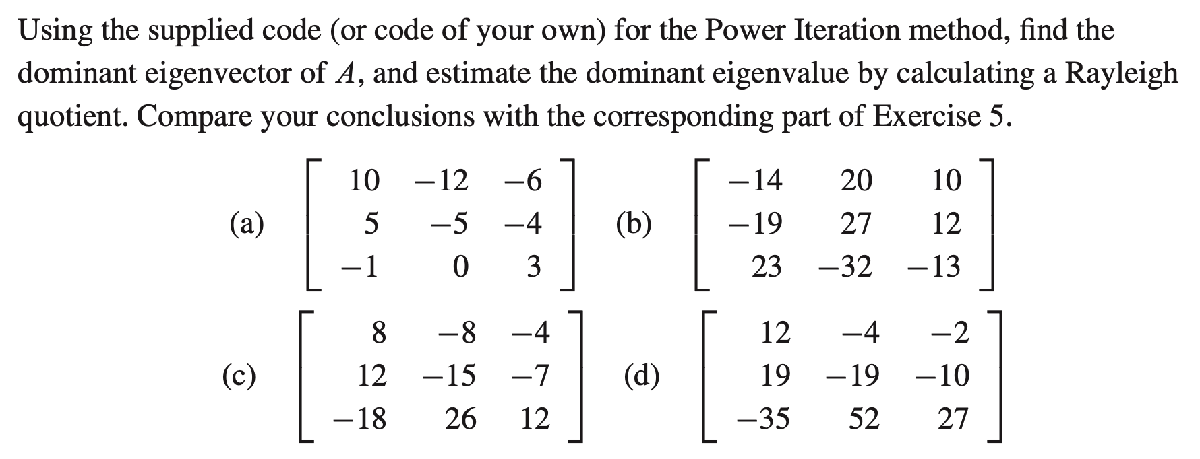

### a)

A=[10, -12,  -6 ;
	5,  -5,  -4 ;
   -1,   0,   3 ];

u0=[1;
	1;
	1];

[lam,u]=power_iteration(A,u0,100);
fprintf('fra oppgave E5 fant vi konvergens mot egenverdien 4, og her får vi: %d',lam);

fra oppgave E5 fant vi konvergens mot egenverdien 4, og her får vi: 4.000000e+00

## CP2 

### 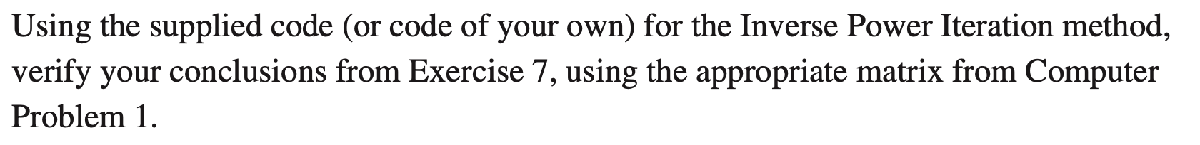

### a)

[lam,u]=power_iteration_inverse(A,u0,0,100);
fprintf('fra oppgave E7 fant vi konvergens mot egenverdien 1, og her får vi: %d',lam);

fra oppgave E7 fant vi konvergens mot egenverdien 1, og her får vi: 1.000000e+00

## CP3 

### 

### a)

[lam,u]=power_iteration_inverse(A,u0,5,100);
fprintf('fra oppgave E8 fant vi konvergens mot egenverdien 4, og her får vi: %d',lam);

fra oppgave E8 fant vi konvergens mot egenverdien 4, og her får vi: 4

## CP4 

### 

### a)

[lam1,u1]= RayleightQIter(A,u0,10);

[lam,u0]=power_iteration_inverse(A,u0,2.9,1);
[lam2,u2]= RayleightQIter(A,u0,5);

u0=[1,0,0]';
[lam3,u3]= RayleightQIter(A,u0,5); 
disp([ u1 u2 u3 ])

                 NaN   0.000000000000000   0.609200483888725
                 NaN   0.447213595499958   0.576136743284334
                 NaN  -0.894427190999916  -0.544923135375500



Da har vi funnet alle tre egenverdiene:

disp([ lam1 lam2 lam3 ]')

                 NaN
   3.000000000000000
   4.065101778221855

